产生瑞利衰落和莱斯衰落信道

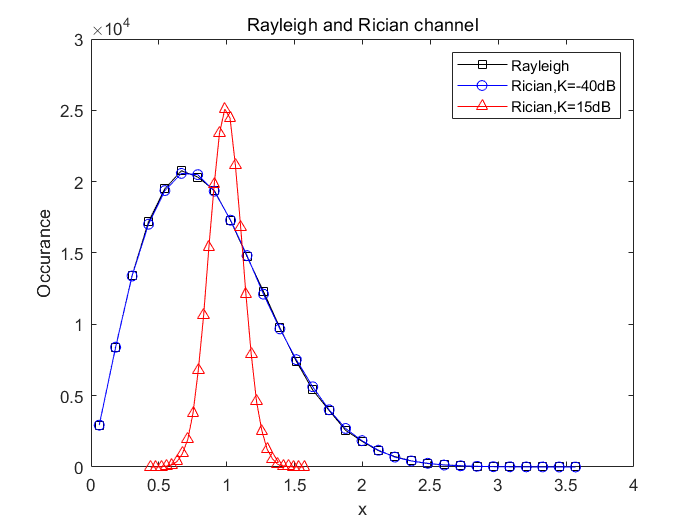

clear,clf,clc,close
N = 200000;
level = 30;
K_dB = [-40 15];
gss = ['k-s';'b-o';'r-^'];
Rayleigh_ch = Ray_model(N);
[Y,E] = histcounts(abs(Rayleigh_ch(1,:)),level);
E = filter([0.5 0.5],1,E);
plot(E(1,2:end),Y(1,:),gss(1,:));hold on
Rician_ch = zeros(length(K_dB),N);
for ni = 1:length(K_dB)
    Rician_ch(ni,:)=Ric_model(K_dB(ni),N);
    [Y,E] = histcounts(abs(Rician_ch(ni,:)),level);
    E = filter([0.5 0.5],1,E);
    plot(E(1,2:end),Y(1,:),gss(ni+1,:));
end
xlabel('x'),ylabel('Occurance')
legend('Rayleigh','Rician,K=-40dB','Rician,K=15dB')
title('Rayleigh and Rician channel')  